## Problema 11 

Considrem l'estructura consistent en dos cilindres i una molla.

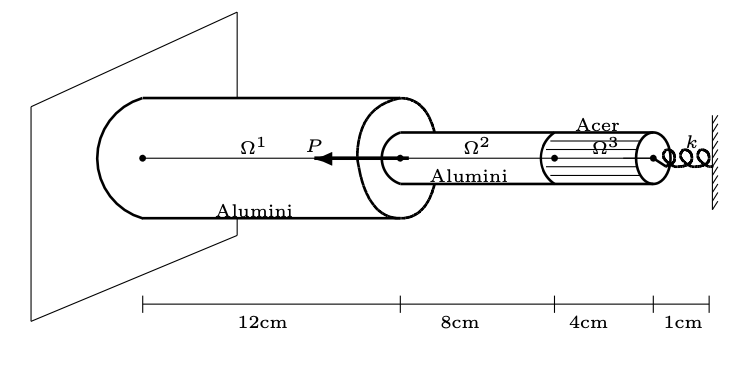

El cilindre de l'esquerra té longitud $12\text{cm}$i diàmetre $4 \text{cm}$. El cilindre de la dreta té longitud $12 \text{cm}$i diàmetre $2 \text{cm}$. Els mòduls de Young són $E_{a} = 10^{6} \text{N/cm}^{2}$ per a l'alumini i $E_{s} = 3\times 10^{6} \text{N/cm}^{2}$per a l'acer. A més sabem que la constant de recuperació de la molla és $k = 10^{9} \text{N/cm}$. Suposem que l'extrem de l'esquerra està fixat i que la condició de contorn que correspon a l'extrem de la dret de la malla és  $EA \frac{\mathrm{d} u}{\mathrm{d} x} + ku = 0$. Suposem que en l'extrem dret del cilindre de l'esquerra hi ha una força $P = 15\text{N}$, tal com es mostra a la figura. Si considerem els elements finits lineals que es mostren a la figura:

    (a) Trobeu les matrius de rigides elementats.

    (b) Trobeu la matriu de rigidesa global i escriviu el sistema lineal global.

    (c) Indiqueu les condicions de contorn.

    (d) Trobeu els desplaçaments $U_{1}, U_{2}, U_{3}$, i $U_{4}$.

(*Indicació: *L'equació que modela el desplaçament lineal és $-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A \frac{\mathrm{d} u}{\mathrm{d} x}\right) = 0$.)

### Solució

#### (a) Matrius de rigidesa elementals

Comparant l'equació de l'elasticitat amb l'equació model,


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(a_{1}(x)\frac{\mathrm{d} u}{\mathrm{d} x}\right) + a_{0}(x) u = f(x), $$


veiem que $a_{1}(x) = A_{e} E_{e}$, $e = 1, 2, 3$;  $a_{0}(x) = 0; f(x) = 0$ per a $0\le x\le 24$. Aleshores les matrius de rigidesa *locals *dels elements són,

- Per a $\Omega^{1}$: $E_{1} = E_{a} = 10^{6} \text{N/cm}^{2}$, $A_{1} = 4\pi \text{cm}^{2}$, $h^{1} = 12\text{cm}$. Per tant: $K^{1} = K^{1,1} = \frac{E_{1} A_{1}}{h_{1}}\left(\!\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\!\right) = \frac{10^{6}\pi}{24}\left(\!\begin{array}{rr} 8 & -8\\ -8 & 8\end{array}\!\right)$.

- Per a $\Omega^{2}$: $E_{2} = E_{a} = 10^{6} \text{N/cm}^{2}$, $A_{2} = \pi \text{cm}^{2}$, $h^{2} = 8\text{cm}$. Per tant: $K^{2} = K^{2,1} = \frac{E_{2} A_{2}}{h_{2}}\left(\!\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\!\right) = \frac{10^{6}\pi}{24}\left(\!\begin{array}{rr} 3 & -3\\ -3 & 3\end{array}\!\right)$.

- Per a $\Omega^{3}$: $E_{3} = E_{a} = 3\times 10^{6} \text{N/cm}^{2}$, $A_{3} = \pi \text{cm}^{2}$, $h^{3} = 4\text{cm}$. Per tant: $K^{3} = K^{3,1} = \frac{E_{3} A_{3}}{h_{3}}\left(\!\begin{array}{rr} 1 & -1\\ -1 & 1\end{array}\!\right) = \frac{10^{6}\pi}{24}\left(\!\begin{array}{rr} 18 & -18\\ -18 & 18\end{array}\!\right)$.

**Remarca. **Notem que $K^{1,0} = K^{2,0} = K^{3,0} = 0$ atès que $a_{0} = 0$ al llarg de tot el domini.

#### (b) Matriu de rigidesa global i sistema lineal


$$\frac{10^{6}\pi}{24}\left(\!\begin{array}{rrrr}
8 & -8 & &\\
-8 & 11 & -3 &\\
& -3 & 21 & -18\\
& & -18 & 18\end{array}\!\right) 
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) = 
\left(\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}
\end{array}\right),
$$


on $K = \frac{10^{6}\pi}{24}\left(\!\begin{array}{rrrr} 8 & -8 & &\\ -8 & 11 & -3 &\\ & -3 & 21 & -18\\ & & -18 & 18\end{array}\!\right)$ és la matriu de rigidesa global i $Q=\left(\begin{array}{c} Q_{1}\\ Q_{2}\\ Q_{3}\\ Q_{4} \end{array}\right) =
\left(\begin{array}{c} Q_{1}^{1} \\ Q_{2}^{1} + Q_{1}^{2}\\  Q^{2}_{2} + Q^{3}_{1}\\ Q_{3}^{2} \end{array}\right)$.

**Remarca. **La matriu de connectivitat és  $B = \left(\begin{array}{cc} 1 & 2\\ 2 & 3\\4 & 4\end{array}\right)$, i notem que $F^{e}_{i} = 0$ per a cada $i = 1,2$ i cada $e = 1,2,3$; atès que $f(x) = 0$ per a tot $0\le x \le 24$; amb la qual cosa $F=\left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3}\\ F_{4} \end{array}\right) = \left(\begin{array}{c} F_{1}^{1} \\ F_{2}^{1} + F_{1}^{2}\\  F^{2}_{2} + F^{3}_{1}\\ Ff_{3}^{2} \end{array}\right) = \left(\begin{array}{c} 0 \\  0\\  0\\ 0 \end{array}\right)$.

#### (c) Condicions de  contorn (B.C.)

- Naturals (sobre les variables secundàries, les Q's): $Q_{2} = Q^{1}_{2} + Q^{2}_{1} = -P = -15 N$, $Q_{3} = Q_{2}^{2} + Q^{3}_{1}  = 0$, i$Q_{4} = Q^{3}_{2} =  E_{3} A_{3}\frac{\mathrm{d} u}{\mathrm{d} x}(18) = -kU_{4} = -10^{9} U_{4}$ (en $\text{N}$, si expressem $U_{4}$ en $\text{cm}$). 

- Essencial (sobre les variables primèries, les $U$'s): $U_{1} = 0$

#### (d) Desplaçaments $U_{1}, U_{2}, U_{3}$, i $U_{4}$.

Amb les condicions de contorn el sistema global s'escriu com 


$$\frac{10^{6}\pi}{24}\left(\!\begin{array}{rrrr}
8 & -8 & &\\
-8 & 11 & -3 &\\
& -3 & 21 & -18\\
& & -18 & 18\end{array}\!\right) 
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) = 
\left(\begin{array}{c}
Q_{1}\\
-P\\
0\\
-10^{9} U_{4}
\end{array}\right),
$$


el qual es pot reescriure com,


$$\frac{10^{6}\pi}{24}\left(\!\begin{array}{rrrc}
8 & -8 & &\\
-8 & 11 & -3 &\\
& -3 & 21 & -18\\
& & -18 & 18+ \frac{24\times 10^{3}}{\pi}\end{array}\!\right) 
\; \left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) = 
\left(\begin{array}{r}
Q_{1}\\
-P\\
0\\
0
\end{array}\right).
$$


D'on tenim que el sistema reduït és,


$$\frac{10^{6}\pi}{24}\left(\!\begin{array}{rrc}

 11 & -3 &\\
 -3 & 21 & -18\\
 & -18 & 18+ \frac{24\times 10^{3}}{\pi}\end{array}\!\right) 
\; \left(\begin{array}{c}
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) = 
\left(\begin{array}{r}
-P\\
0\\
0
\end{array}\right).
$$


La solució d'aquest últim sistema, juntament amb la condició inicial $U_{1} = 0$, ens dóna els desplaçament des nodes, els quals resulten:

  
$$\text{\bf Solució:}\left\{\begin{array}{l}
U_{1} = \ \ 0 \text{ cm (de la condició de contorn essencial) },\\
U_{2} = -1.08406\times 10^{-5} \text{cm},\\
U_{3} = -1.55179\times 10^{-6} \text{cm},\\
U_{4} = -3.64772\times 10^{-9} \text{cm}.
\end{array}\right.$$


clearvars
close all

%Real constants
E = [1.0e6, 1.0e6, 3.0e6]; %N/cm^2
A = pi*[4, 1, 1];             %cm^2        
k = 1.0e9;                    %N/cm

%Geometry
nodes = [0; 12; 20; 24];      %cm
numNodes = size(nodes,1);

%Loads
P =  15;                      %N

elem = [1:numNodes-1; 2:numNodes]';
numElem = size(elem,1);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);

for e = 1:numElem
    rows = [elem(e,1); elem(e,2)];
    cols = rows;

    x1 = nodes(rows(1)); x2 = nodes(rows(2));
    h = x2 - x1;

    Ke = A(e)*E(e)*[1,-1;-1,1]/h;
    K(rows,cols) = K(rows,cols) + Ke;

end

fixedNodes = 1;
freeNodes = setdiff(1:numNodes, fixedNodes);

%B.C.:

%Natural B.C.
Q(2) = -P;
K(numNodes,numNodes) = K(numNodes, numNodes) + k;

%Essential B.C.
u = zeros(numNodes,1);
u(1) = 0;

%Reduced Sustem
Fm = Q(freeNodes) - K(freeNodes, fixedNodes)*u(fixedNodes); %No necessary (here u(fixedNodes) = 0)
Km = K(freeNodes,freeNodes);

%Solution of the reduced sustem
um = Km\Fm;
u(freeNodes) = um;
fprintf('%12.5e %12.5e cm\n',[nodes,u]')

 0.00000e+00  0.00000e+00 cm
 1.20000e+01 -1.08406e-05 cm
 2.00000e+01 -1.55179e-06 cm
 2.40000e+01 -3.64772e-09 cm
